## Dynamics Function:

**Description:** This function uses convervation of angular momentum to model the dynamics of the spacecraft. 

**Inputs:**

    $x$: 7x1 vector comprised of $\delta$ (4x1 vector of cmg gimbal angles) and $\omega$ (3x1 vector of angular velocity of spacecraft).

    $\overset{\cdot }{\delta}$: 4x1 vector of angular velocity of cmg gimbal. This is our control input.

**Outputs:**

    $\overset{\cdot }{x}$: 7x1 vector comprised of $\overset{\cdot }{\delta}$ (4x1 vector of cmg gimbal angular velocities) and $\overset{\cdot }{\omega}$ (3x1 vector of angular acceleration of spacecraft).

**System Parameters:**

    The physical parametes of the spacecraft are listed in this function and are comprised of:

        $\Omega$: cmg rotor angular velocity (assumed to be constant)

        $I$: 3x3 vector of moment of interia of spacecraft

        $I_r$: moment of interial of CMG measured along rotor (2nd and 3rd axes of MOI are assumed to be neglibable)

        $\beta$: geometric property of spacecraft (see image below)

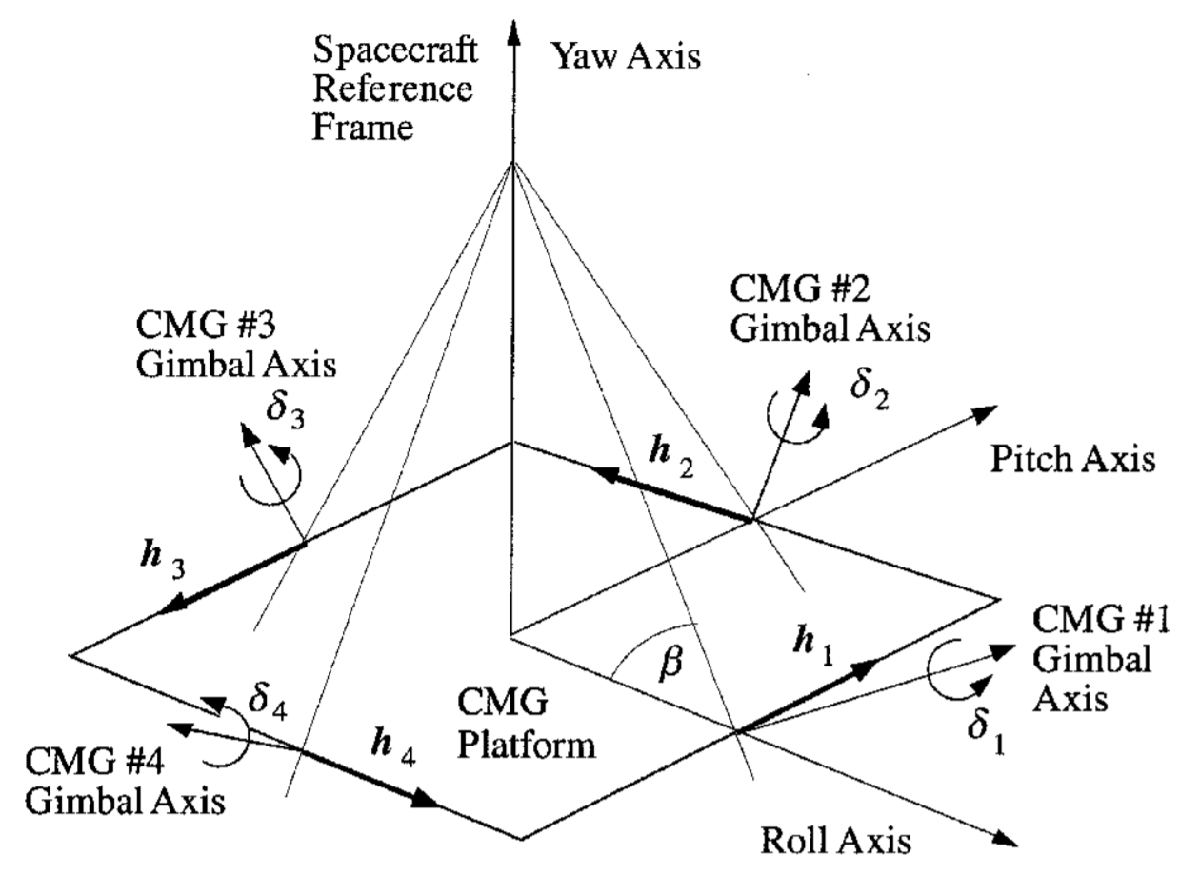[1]

[1] Wie, Bong & Bailey, David & Heiberg, Christopher. (2001). Singularity Robust Steering Logic for Redundant Single-Gimbal Control Moment Gyros. Journal of Guidance Control and Dynamics - J GUID CONTROL DYNAM. 24. 865-872. 10.2514/2.4799. 

**Equations:**

    As stated previously, we will be using conservation of angular momentum to solve the dynamics of the system. We can write the change in angular momentum as the following:

        
$$\begin{array}{l}
\overset{\cdot }{H} =I\overset{\cdot }{\omega} +I_r \Omega \left\lbrack \begin{array}{cccc}
-\sin \left(\beta \right)\cos \left(\delta_1 \right) & \sin \left(\delta_2 \right) & \sin \left(\beta \right)\cos \left(\delta_3 \right) & -\sin \left(\delta_4 \right)\\
\sin \left(\delta_1 \right) & \sin \left(\beta \right)\cos \left(\delta_2 \right) & -\sin \left(\delta_3 \right) & -\sin \left(\beta \right)\cos \left(\delta_4 \right)\\
\cos \left(\beta \right)\cos \left(\delta_1 \right) & \cos \left(\beta \right)\cos \left(\delta_2 \right) & \cos \left(\beta \right)\cos \left(\delta_3 \right) & \cos \left(\beta \right)\cos \left(\delta_4 \right)
\end{array}\right\rbrack \overset{\cdot }{\delta} \\
+\omega \times I\omega \left\lbrack \begin{array}{cccc}
-\sin \left(\beta \right)\sin \left(\delta_1 \right) & -\cos \left(\delta_2 \right) & \sin \left(\beta \right)\sin \left(\delta_3 \right) & \cos \left(\delta_4 \right)\\
-\cos \left(\delta_1 \right) & \sin \left(\beta \right)\sin \left(\delta_2 \right) & \cos \left(\delta_3 \right) & -\sin \left(\beta \right)\sin \left(\delta_4 \right)\\
\cos \left(\beta \right)\sin \left(\delta_1 \right) & \cos \left(\beta \right)\sin \left(\delta_2 \right) & \cos \left(\beta \right)\sin \left(\delta_3 \right) & \cos \left(\beta \right)\sin \left(\delta_4 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
\tau 
\end{array}\right\rbrack 
\end{array}$$


but by conservation of angular momemtum, $\overset{\cdot }{H} =0$. So we can rewrite the equation to solve for $\overset{\cdot }{\omega}$:

        
$$\overset{\cdot }{\omega} ={-I}^{-1} \left(I_r \Omega \left\lbrack \begin{array}{cccc}
-\sin \left(\beta \right)\cos \left(\delta_1 \right) & \sin \left(\delta_2 \right) & \sin \left(\beta \right)\cos \left(\delta_3 \right) & -\sin \left(\delta_4 \right)\\
\sin \left(\delta_1 \right) & \sin \left(\beta \right)\cos \left(\delta_2 \right) & -\sin \left(\delta_3 \right) & -\sin \left(\beta \right)\cos \left(\delta_4 \right)\\
\cos \left(\beta \right)\cos \left(\delta_1 \right) & \cos \left(\beta \right)\cos \left(\delta_2 \right) & \cos \left(\beta \right)*\cos \left(\delta_3 \right) & \cos \left(\beta \right)\cos \left(\delta_4 \right)
\end{array}\right\rbrack \overset{\cdot }{\delta} +\omega \times I\omega \left\lbrack \begin{array}{cccc}
-\sin \left(\beta \right)\sin \left(\delta_1 \right) & -\cos \left(\delta_2 \right) & \sin \left(\beta \right)\sin \left(\delta_3 \right) & \cos \left(\delta_4 \right)\\
-\cos \left(\delta_1 \right) & \sin \left(\beta \right)\sin \left(\delta_2 \right) & \cos \left(\delta_3 \right) & -\sin \left(\beta \right)\sin \left(\delta_4 \right)\\
\cos \left(\beta \right)\sin \left(\delta_1 \right) & \cos \left(\beta \right)\sin \left(\delta_2 \right) & \cos \left(\beta \right)\sin \left(\delta_3 \right) & \cos \left(\beta \right)\sin \left(\delta_4 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
\tau 
\end{array}\right\rbrack \right)$$



function xdot = dynamics(t,x,tspan,delta_dot)

% Construct delta_dot for ode45
delta_dot1 = interp1(tspan, delta_dot(1,:), t);
delta_dot2 = interp1(tspan, delta_dot(2,:), t);
delta_dot3 = interp1(tspan, delta_dot(3,:), t);
delta_dot4 = interp1(tspan, delta_dot(4,:), t);
delta_dot = [delta_dot1;delta_dot2;delta_dot3;delta_dot4];

% unpack delta and omega
delta = x(1:4);
omega = x(5:7);

% sytem properties
Omega = double("300"); % rotor angular velocity (fast, in rad/s)
I = 0*rand([3,3]); % spacecraft moment of inertia (placeholder)
I(1,1) = double(200);   % Ixx (kg*m^2)
I(2,2) = double(200); % Iyy (kg*m^2)
I(3,3) = double(200); % Izz (kg*m^2)
I_r = double(5); % Izz of CMG (kg*m^2) measured along rotor axis
beta = pi/3; % geometric property of spacecraft
m = 100; % mass of total system (kg)

% % low / high
% coef_friction_slip = 0.04; % coefficient of friction under slip conditions
% coef_friction_stick = 0.6; % coefficient of friction under stick conditions

% % low / moderate
% coef_friction_slip = 0.04; % coefficient of friction under slip conditions
% coef_friction_stick = 0.3; % coefficient of friction under stick conditions

% low / low
coef_friction_slip = 0.04; % coefficient of friction under slip conditions
coef_friction_stick = 0.04; % coefficient of friction under stick conditions

h = [-sin(beta)*sin(delta(1)) - cos(delta(2)) + sin(beta)*sin(delta(3)) + cos(delta(4));
     -cos(delta(1)) + sin(beta)*sin(delta(2)) + cos(delta(3)) + -sin(beta)*sin(delta(4));
     cos(beta)*sin(delta(1)) + cos(beta)*sin(delta(2)) + cos(beta)*sin(delta(3)) + cos(beta)*sin(delta(4))];

A = [-sin(beta)*cos(delta(1)), sin(delta(2)), sin(beta)*cos(delta(3)), -sin(delta(4));
      sin(delta(1)), sin(beta)*cos(delta(2)), -sin(delta(3)), -sin(beta)*cos(delta(4));
     cos(beta)*cos(delta(1)), cos(beta)*cos(delta(2)), cos(beta)*cos(delta(3)), cos(beta)*cos(delta(4))];

eps = 1e-3;
if abs(omega(3)) < eps
    F = -coef_friction_stick*m*9.81*omega(3)/eps;
else
    F = -coef_friction_slip*m*9.81*sign(omega(3));
end

tau = F*1;

omega_dot = -I\(I_r*Omega*A*delta_dot + cross(omega,I*omega) + cross(omega,I_r*Omega*h) - [0;0;tau]);

omega = [0;0;omega_dot(3)];
delta = delta_dot;



xdot = [delta;omega];
end